# **Analysis of the Burgers equation by LSUN**

First run TanSacNet/code/setpath

Requirements: MATLAB R2022b 

Contact address: Shogo MURAMATSU, Faculty of Engineering, Niigata University, 8050 2-no-cho Ikarashi, Nishi-ku, Niigata, 950-2181, JAPAN http://msiplab.eng.niigata-u.ac.jp  

Copyright (c) 2023, Hayato Obara and Shogo MURAMATSU, All rights reserved.

clc, clear
close all

% Data folder
datafolder = "../../../data/";


Parameters

% LSUN train
numEpochs = 600;
nCoefs = 2; 
pt = 2;
stride = 2*pt; % Stride (even)

nu = 0.05;
% td-DMD
nDelay = 1;

## Input data

filenameinput = "burgerseq";
if exist(datafolder+filenameinput+"nu_"+replace(num2str(nu),'.','_')+".mat","file")~=2
    main_burgerseq_gen(datafolder+filenameinput,nu)
else
    disp("Data found!")
end

Data found!


Sload = load(datafolder+filenameinput+"nu_"+replace(num2str(nu),'.','_'),"T","X","DataT","dt","dx");
T = Sload.T;
X = Sload.X;
dt = Sload.dt;
dx = Sload.dx;
DataT = Sload.DataT;

## **Data visualisation**

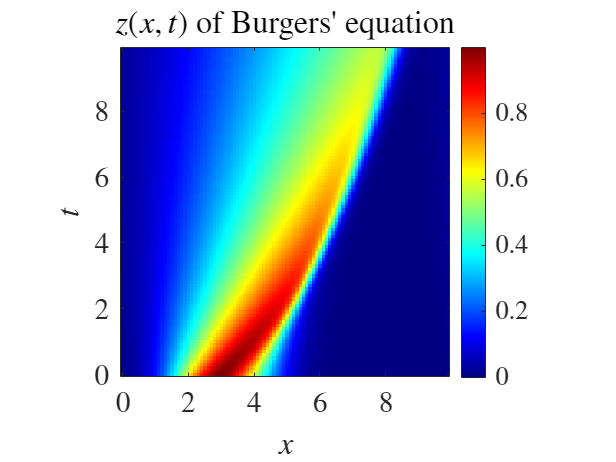

figure
ax = disp_imagesc_(T,X,DataT," $z(x,t)$ of Burgers' equation");
exportgraphics(ax,'fig03a.png')

## LSUN training

nX = size(DataT,2);
filenamelsun = datafolder + "lsunnet_nX"+num2str(nX)+"_stride" + num2str(stride)+"_nCoefs"+num2str(nCoefs) + "_numEpochs" + num2str(numEpochs);
if exist(filenamelsun+".mat","file")~=2
    [analsunnet, synlsunnet,coefMask] = fcn_lsun_train(DataT,stride,nCoefs,numEpochs);
    save(filenamelsun,"analsunnet","synlsunnet","nX","stride","nCoefs","numEpochs","coefMask");
else
    disp("LSUN found!")
end

LSUN found!


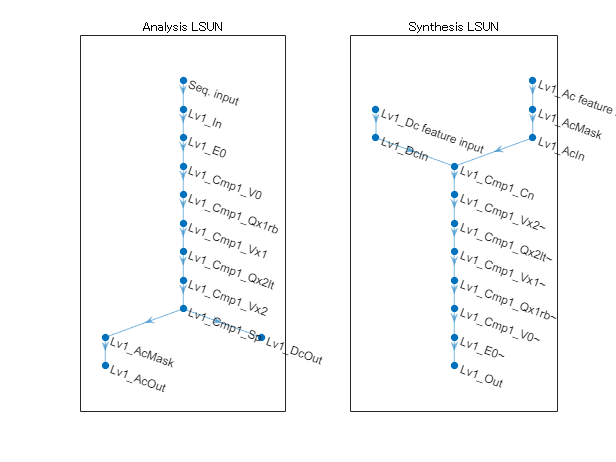

Slsun = load(filenamelsun,"analsunnet","synlsunnet","nX","stride","nCoefs","coefMask");
analsunnet = Slsun.analsunnet;
synlsunnet = Slsun.synlsunnet;
coefMask = Slsun.coefMask;
stride = Slsun.stride;
nCoefs = Slsun.nCoefs;


figure
subplot(1,2,1)
plot(analsunnet)
title('Analysis LSUN')
subplot(1,2,2)
plot(synlsunnet)
title('Synthesis LSUN')

### Analysis process

nT = size(DataT,1);
ndim = nX

ndim = 100

analsunseq = zeros(nT,stride,ndim/stride,'like',DataT);
for iT = 1:nT
    [dc,ac] = analsunnet.predict(gpuArray(DataT(iT,:))); % dc: 1 x Pos., ac: Ch. x 1 x Pos
    analsunseq(iT,:,:) = cat(2,permute(dc,[3 1 2]),permute(ac,[2 1 3]));
end
% 3-D array w/ Time x Ch. x Pos.
size(analsunseq)

ans =    100     4    25


### Synthesis process

synlsunnet.Layers(11).InputSize

ans =      3     1    25


synlsunnet.Layers(12).InputSize

ans =      1     1    25


synlsunseq = analsunseq;
DataTaprx = zeros(size(DataT),'like',DataT);
for iT = 1:nT
    ac = permute(synlsunseq(iT,2:end,:),[2 1 3]);   
    dc = synlsunseq(iT,1,:);
    DataTaprx(iT,:) = synlsunnet.predict(ac,dc);    
end

### td-DMD


nRange = size(analsunseq,1); 

size(analsunseq) % K x Ch. x Pos.

ans =    100     4    25


matS = eye(stride);
matS = matS(coefMask==1,:)

matS =      1     0     0     0
     0     0     1     0


dataY = pagemtimes(matS, permute(analsunseq,[2 1 3])); % Ch. x K x Pos.
dataX = reshape(ipermute(dataY,[2 1 3]),nRange,[]) % K x (Ch.Pos.)

dataX =     0.0367   -0.0111    0.1052   -0.0271    0.2564   -0.0520    0.5327   -0.0817    0.9426   -0.0971    1.4211   -0.0411    1.8218   -0.0426    1.9847    0.0524    1.8405    0.2030    1.4111    0.4171    0.8096    0.5862    0.3288    0.4557    0.1194    0.2282    0.0637    0.1059    0.0265    0.0394    0.0118    0.0118    0.0036    0.0029    0.0015    0.0007    0.0000    0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0025
    0.0362   -0.0128    0.1063   -0.0268    0.2534   -0.0497    0.5142   -0.0755    0.8932   -0.0886    1.3400   -0.0400    1.7435   -0.0541    1.9623    0.0294    1.8915    0.1899    1.4929    0.4336    0.8626    0.6249    0.3464    0.4829    0.1239    0.2390    0.0663    0.1102    0.0276    0.0409    0.0123    0.0123    0.0038    0.0031    0.0016    0.0007    0.0000    0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0023 

% Construction of Hankel matrix
x = dataX;

ts = [];
H = [];
%nRange = size(x,1)-1;
nRange = size(x,1);
for k = 0:nRange-nDelay-1
    xkT = [];
    for iDelay = 0:nDelay
        xkT = cat(2,xkT,x(k+iDelay+1,:));
    end
    H = cat(2,H,xkT.');
end
H

H =     0.0367    0.0362    0.0367    0.0373    0.0381    0.0389    0.0397    0.0406    0.0414    0.0423    0.0431    0.0439    0.0447    0.0454    0.0462    0.0469    0.0476    0.0483    0.0489    0.0495    0.0501    0.0507    0.0513    0.0518    0.0523    0.0528    0.0533    0.0538    0.0542    0.0547    0.0551    0.0555    0.0558    0.0562    0.0566    0.0569    0.0572    0.0575    0.0578    0.0581    0.0584    0.0586    0.0589    0.0591    0.0594    0.0596    0.0598    0.0600    0.0602    0.0604
   -0.0111   -0.0128   -0.0132   -0.0133   -0.0133   -0.0132   -0.0132   -0.0131   -0.0130   -0.0129   -0.0129   -0.0128   -0.0127   -0.0126   -0.0125   -0.0124   -0.0123   -0.0122   -0.0121   -0.0121   -0.0120   -0.0118   -0.0117   -0.0116   -0.0115   -0.0114   -0.0113   -0.0112   -0.0111   -0.0110   -0.0109   -0.0108   -0.0107   -0.0106   -0.0105   -0.0104   -0.0103   -0.0102   -0.0101   -0.0100   -0.0099   -0.0098   -0.0097   -0.0096   -0.0095   -0.0094   -0.0093   -0.0092   -0.0091   -0

Step 2 SVD of H

[U,Sgm,V] = svd(H,'econ')

U =    -0.0126    0.0062   -0.0021   -0.0028   -0.0013   -0.0018   -0.0012   -0.0012   -0.0013   -0.0007   -0.0016    0.0003   -0.0020   -0.0004    0.0026   -0.0014    0.0036   -0.0026    0.0047   -0.0042    0.0061   -0.0059    0.0112   -0.0192    0.0099    0.0140    0.0232    0.0370    0.0371    0.0391    0.0572    0.0624    0.0835    0.0743    0.0944    0.1186    0.1563    0.0088    0.0671    0.0905    0.0548    0.1482    0.1172   -0.0857    0.0618   -0.0459   -0.0272   -0.0365    0.0182    0.0108
    0.0021    0.0008    0.0003   -0.0002    0.0001   -0.0001   -0.0001    0.0002   -0.0003    0.0005   -0.0007   -0.0009   -0.0014   -0.0017    0.0023   -0.0031    0.0040   -0.0051    0.0059   -0.0080    0.0086   -0.0117    0.0176   -0.0329    0.0141    0.0249    0.0383    0.0619    0.0604    0.0642    0.0905    0.1014    0.1275    0.1190    0.1306    0.1780    0.2290    0.1505    0.1655   -0.0609    0.0706    0.1082    0.1057   -0.0682    0.0834   -0.0360    0.1218   -0.0477    0.0200   -0

Sgm =    44.2104         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   19.5153         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

V =    -0.0973   -0.1595   -0.1750    0.1818   -0.1873    0.1927   -0.1979    0.2029   -0.2072    0.2113   -0.2142   -0.2127   -0.2250   -0.2106    0.2096   -0.2188    0.2159   -0.2097    0.1854   -0.1906    0.1651   -0.1549    0.2119   -0.2110    0.0742    0.1100    0.1131    0.1341    0.0963    0.0727    0.0742    0.0632    0.0614    0.0434    0.0332    0.0357    0.0259    0.0020    0.0075    0.0086    0.0050    0.0076    0.0040   -0.0014    0.0009   -0.0005    0.0000   -0.0003    0.0002    0.0000
   -0.0985   -0.1602   -0.1716    0.1728   -0.1709    0.1678   -0.1625    0.1559   -0.1466    0.1356   -0.1218   -0.1030   -0.0901   -0.0639    0.0404   -0.0172   -0.0094    0.0375   -0.0604    0.0914   -0.1008    0.1304   -0.1925    0.2870   -0.1122   -0.1809   -0.2221   -0.2981   -0.2403   -0.2046   -0.2326   -0.2156   -0.2293   -0.1751   -0.1544   -0.1755   -0.1522   -0.0197   -0.0572   -0.0475   -0.0352   -0.0611   -0.0388    0.0181   -0.0116    0.0067   -0.0039    0.0061   -0.0043   -0

Step 3 PCT

iMode = 1

iMode = 1

ui = reshape(U(:,iMode),size(x,2),[]).'

ui =    -0.0126    0.0021   -0.0237    0.0032   -0.0399    0.0042   -0.0617    0.0050   -0.0886    0.0051   -0.1193    0.0013   -0.1517    0.0058   -0.1830    0.0039   -0.2108   -0.0079   -0.2293   -0.0438   -0.2164   -0.1238   -0.1740   -0.1814   -0.1537   -0.1636   -0.1519   -0.1488   -0.1419   -0.1202   -0.1362   -0.0853   -0.1218   -0.0420   -0.1027   -0.0534   -0.0571   -0.0370   -0.0262   -0.0134   -0.0100   -0.0054   -0.0032   -0.0009   -0.0011    0.0002   -0.0025    0.0006   -0.0059    0.0018
   -0.0126    0.0021   -0.0237    0.0032   -0.0396    0.0041   -0.0609    0.0048   -0.0869    0.0048   -0.1166    0.0012   -0.1482    0.0057   -0.1791    0.0040   -0.2074   -0.0075   -0.2270   -0.0430   -0.2156   -0.1231   -0.1744   -0.1814   -0.1548   -0.1643   -0.1534   -0.1499   -0.1437   -0.1214   -0.1383   -0.0864   -0.1243   -0.0424   -0.1051   -0.0547   -0.0593   -0.0384   -0.0280   -0.0140   -0.0114   -0.0056   -0.0037   -0.0011   -0.0012    0.0001   -0.0026    0.0006   -0.0060    

V0 = V(1:end-1,:);
V1 = V(2:end,:);
dtAplusI = (V1.')*pinv(V0.') 

dtAplusI =     0.9923    0.0131   -0.0073   -0.0104   -0.0099   -0.0110   -0.0113   -0.0119   -0.0123   -0.0128   -0.0128    0.0140   -0.0139    0.0140    0.0142    0.0142    0.0139    0.0133    0.0145    0.0149    0.0138    0.0183    0.0106    0.0048    0.0252   -0.0124    0.0059   -0.0052    0.0069   -0.0093    0.0116   -0.0145    0.0127   -0.0102    0.0094   -0.0063    0.0016   -0.0035    0.0030   -0.0090    0.0087   -0.0031    0.0010    0.0023   -0.0031   -0.0100   -0.0002   -0.0011   -0.0036    0.0007
   -0.0207    0.9813    0.0301    0.0090    0.0167    0.0141    0.0161    0.0160    0.0170    0.0174    0.0176   -0.0191    0.0189   -0.0191   -0.0194   -0.0193   -0.0190   -0.0182   -0.0198   -0.0204   -0.0188   -0.0249   -0.0145   -0.0065   -0.0344    0.0169   -0.0080    0.0071   -0.0094    0.0127   -0.0158    0.0198   -0.0173    0.0139   -0.0128    0.0086   -0.0022    0.0048   -0.0041    0.0123   -0.0119    0.0042   -0.0013   -0.0031    0.0042    0.0136    0.0003    0.0015    0.00

Step 4 Discover forcinge signal

v0hat = V(1,:).';
vk = v0hat;
dtrk_ = 0;
dtr = [];
for k = 1:nRange-nDelay-1
    % True value
    vkp1 = V(k+1,:).';
    % Forcasted value
    vkp1hat = dtAplusI*vk;
    % Forcing signal
    dtrk_ = vkp1 - vkp1hat;
    % Update
    vk = vkp1;
    dtr = cat(2,dtr,dtrk_);
end

Learnable parameters

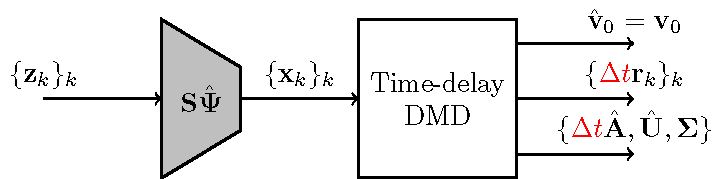

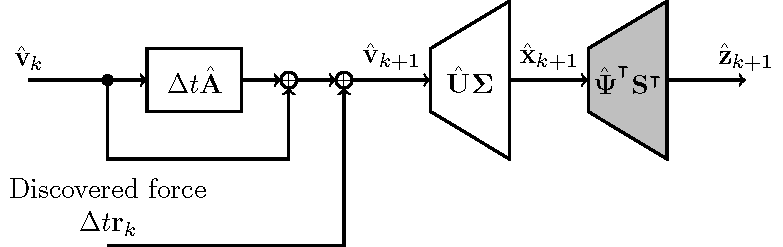

Parameters


$$\hat{\mathbf{v}}_0$$


v0hat

v0hat =    -0.0973
   -0.1595
   -0.1750
    0.1818
   -0.1873
    0.1927
   -0.1979
    0.2029
   -0.2072
    0.2113



$$\{\Delta t \mathbf{r}_k\}$$


dtr

dtr = 1.0e-15 *

   -0.0694   -0.0694   -0.1388   -0.2776   -0.0416   -0.2914   -0.1804    0.0971    0.0694         0   -0.1249    0.3192   -0.2082    0.1665    0.0139   -0.0139    0.3331    0.1665    0.0139   -0.0833   -0.2220   -0.1249   -0.0694   -0.3053   -0.0971    0.0139   -0.1665   -0.0139    0.0971    0.1110   -0.2220   -0.0278         0         0   -0.1110    0.2220   -0.2359   -0.0833   -0.0139   -0.2220    0.3053   -0.1804   -0.0278   -0.2220    0.1527   -0.0139   -0.0555   -0.0694   -0.1527   -0.4996
   -0.0278    0.5551    0.0278   -0.1110   -0.2498    0.4163   -0.1388   -0.0278    0.2498    0.1943    0.1388    0.0833   -0.1110   -0.1665    0.0833    0.1388    0.2220   -0.3469   -0.5135   -0.1249         0    0.1249   -0.1388    0.1527   -0.0833    0.0139    0.0694   -0.0416   -0.0833   -0.0069    0.1457   -0.0278    0.0555   -0.1110    0.1665    0.1006    0.0798    0.0919   -0.3411   -0.3305   -0.1162   -0.1926   -0.1006   -0.0763   -0.1978   -0.0278   -0.1596   -0.1804  


$$\mathbf{I}+\Delta t \hat{\mathbf{A}}$$


dtAplusI

dtAplusI =     0.9923    0.0131   -0.0073   -0.0104   -0.0099   -0.0110   -0.0113   -0.0119   -0.0123   -0.0128   -0.0128    0.0140   -0.0139    0.0140    0.0142    0.0142    0.0139    0.0133    0.0145    0.0149    0.0138    0.0183    0.0106    0.0048    0.0252   -0.0124    0.0059   -0.0052    0.0069   -0.0093    0.0116   -0.0145    0.0127   -0.0102    0.0094   -0.0063    0.0016   -0.0035    0.0030   -0.0090    0.0087   -0.0031    0.0010    0.0023   -0.0031   -0.0100   -0.0002   -0.0011   -0.0036    0.0007
   -0.0207    0.9813    0.0301    0.0090    0.0167    0.0141    0.0161    0.0160    0.0170    0.0174    0.0176   -0.0191    0.0189   -0.0191   -0.0194   -0.0193   -0.0190   -0.0182   -0.0198   -0.0204   -0.0188   -0.0249   -0.0145   -0.0065   -0.0344    0.0169   -0.0080    0.0071   -0.0094    0.0127   -0.0158    0.0198   -0.0173    0.0139   -0.0128    0.0086   -0.0022    0.0048   -0.0041    0.0123   -0.0119    0.0042   -0.0013   -0.0031    0.0042    0.0136    0.0003    0.0015    0.00


$$\hat{\mathbf{U}}$$


rRed = nCoefs/stride;
Uhat = U(1:(ndim*rRed),:);
Uhat

Uhat =    -0.0126    0.0062   -0.0021   -0.0028   -0.0013   -0.0018   -0.0012   -0.0012   -0.0013   -0.0007   -0.0016    0.0003   -0.0020   -0.0004    0.0026   -0.0014    0.0036   -0.0026    0.0047   -0.0042    0.0061   -0.0059    0.0112   -0.0192    0.0099    0.0140    0.0232    0.0370    0.0371    0.0391    0.0572    0.0624    0.0835    0.0743    0.0944    0.1186    0.1563    0.0088    0.0671    0.0905    0.0548    0.1482    0.1172   -0.0857    0.0618   -0.0459   -0.0272   -0.0365    0.0182    0.0108
    0.0021    0.0008    0.0003   -0.0002    0.0001   -0.0001   -0.0001    0.0002   -0.0003    0.0005   -0.0007   -0.0009   -0.0014   -0.0017    0.0023   -0.0031    0.0040   -0.0051    0.0059   -0.0080    0.0086   -0.0117    0.0176   -0.0329    0.0141    0.0249    0.0383    0.0619    0.0604    0.0642    0.0905    0.1014    0.1275    0.1190    0.1306    0.1780    0.2290    0.1505    0.1655   -0.0609    0.0706    0.1082    0.1057   -0.0682    0.0834   -0.0360    0.1218   -0.0477    0.0200  


$$\mathbf{\Sigma}$$


Sgm

Sgm =    44.2104         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   19.5153         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Step 5 w/ Discovered forcing signal

vkhat = v0hat;
%dtrk = dtr(:,1);
Xhat = (Uhat*Sgm*vkhat).';
for k = 1:nRange-nDelay-1
    dtrk = dtr(:,k);
    vkp1hat = dtAplusI*vkhat + dtrk;
    Xhat =  cat(1,Xhat,(Uhat*Sgm*vkp1hat).');
    % Update
    vkhat = vkp1hat;
end

% Reshape results
size(Xhat)  % (K-D) x (Ch.Pos.)

ans =     99    50


nRangeOut = nRange - nDelay;
dataYhat = ipermute((reshape(Xhat,nRangeOut,nCoefs,[])),[2 1 3]); % Ch. x (KxPos)
dataXhat = reshape(ipermute(pagemtimes(matS.',dataYhat),[2 1 3]),nRangeOut,stride,[]); % K x Ch. x Pos.
size(dataXhat)

ans =     99     4    25


% Reconstruction of output to be sent through LSUN synthesizer
synlsunseq = dataXhat;
DataHatTaprx = zeros(nRangeOut,size(DataT,2),'like',DataT);
for iT = 1:nRangeOut
    ac = permute(synlsunseq(iT,2:end,:),[2 1 3]);   
    dc = synlsunseq(iT,1,:);
    DataHatTaprx(iT,:) = synlsunnet.predict(ac,dc);    
end

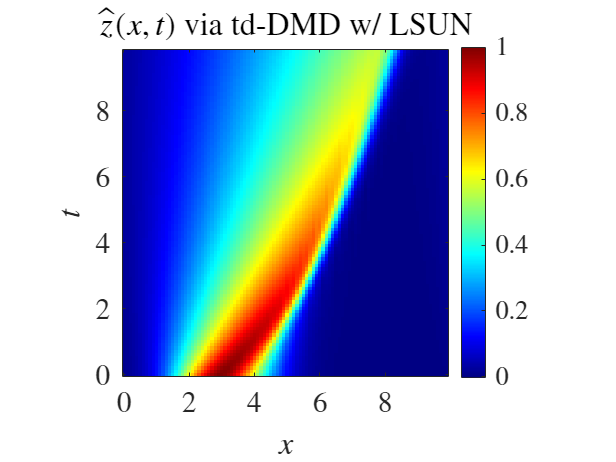

figure
ax = disp_imagesc_(T,X,DataHatTaprx," $\hat{z}(x,t)$ via td-DMD w/ LSUN");
exportgraphics(ax,'fig03c.png')


% MSE評価
mse(DataT(1:nRangeOut,:),DataHatTaprx)

ans = 4.3811e-06

## Discovered forcing signal

r0 = zeros(size(v0hat),'like',v0hat);
%dtrk = dtr(:,1);
Rhat = (Uhat*Sgm*r0).';
for k = 1:nRange-nDelay-1
    dtrk = dtr(:,k);
    rkp1hat = dtrk/dt;
    Rhat =  cat(1,Rhat,(Uhat*Sgm*rkp1hat).');
    % Update
    rkhat = rkp1hat;
end

% Reshape results
size(Rhat)  % (K-D) x (Ch.Pos.)

ans =     99    50


nRangeOut = nRange - nDelay;
dataYhat = ipermute((reshape(Rhat,nRangeOut,nCoefs,[])),[2 1 3]); % Ch. x (KxPos)
dataQhat = reshape(ipermute(pagemtimes(matS.',dataYhat),[2 1 3]),nRangeOut,stride,[]); % K x Ch. x Pos.
size(dataQhat)

ans =     99     4    25


% Reconstruction of output to be sent throughr LSUN synthesizer
synlsunseq = dataQhat;
DataTdfs = zeros(nRangeOut,size(DataT,2),'like',DataT);
for iT = 1:nRangeOut
    ac = permute(synlsunseq(iT,2:end,:),[2 1 3]);   
    dc = synlsunseq(iT,1,:);
    DataTdfs(iT,:) = synlsunnet.predict(ac,dc);    
end

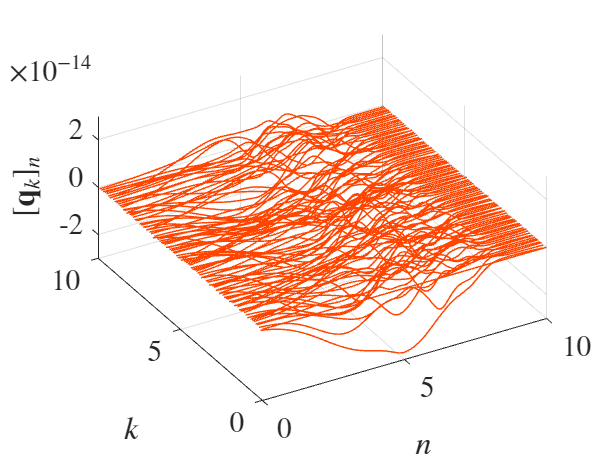


figure
orangered = [255 69 0]/255;
ax = disp_plot3_q_(T(1:size(DataTdfs,1)),X,DataTdfs,orangered);
ax.ZLim = [-3 3]*1e-14;
exportgraphics(ax,'fig04b.png')

disp("||q_k||_2^2/(K-D)")

||q_k||_2^2/(K-D)


size(DataTdfs,1)

ans = 99

norm(DataTdfs,'Fro')/size(DataTdfs,1)

ans = 6.0610e-15

Function definition

function ax = disp_plot3_q_(T,X,DataT,c)
if nargin < 4
 c = 'blue';
end

for idx = 1:length(T)
 plot3(X,T(idx)*ones(size(X)),DataT(idx,:),...
 'Color',c,...
 'LineWidth',1)
 hold on
end
xlabel('$n$', 'Interpreter','latex')
ylabel('$k$', 'Interpreter','latex')
zlabel('$[\mathbf{q}_k]_n$', 'Interpreter','latex')
ax = gca;
ax.View = [-30 30];
ax.PlotBoxAspectRatio = [ 2 2 1];
ax.FontSize = 20;
ax.TickLabelInterpreter = 'latex';

grid on
hold off
end


function ax = disp_imagesc_(T,X,DataT,title_)
imagesc(DataT)
colormap("jet")
cb = colorbar;
cb.TickLabelInterpreter = 'latex';
title(title_,'Interpreter','latex')
xlabel('$x$','Interpreter','latex')
ylabel('$t$','Interpreter','latex')
ax = gca;
ax.PlotBoxAspectRatio = [1 1 1];
ax.XTick = 1:20:100;
ax.XTickLabel = round(X(ax.XTick));
ax.YTick = 1:20:100;
ax.YTickLabel = round(T(ax.YTick));
ax.YDir = 'normal';
ax.FontSize = 20;
ax.TickLabelInterpreter = 'latex';
end